#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

data.gravity = -9.81;
ODE          = Winx( data, false );

#### Initialize the solver class

solver = Heun();
solver.setODE( ODE );

#### Advance the ODE

DT = 0.1;
T  = 180;

s = 0;
theta1 =0;
theta2 =  0.3912390397;   %theta2 =2.750353614;
theta4 = 0.006780333643;   %theta4 = 3.134812320;
theta5 = 0;
theta6 = 0;
s__dot =0;
theta1__dot = 0;
theta2__dot = 0;
theta4__dot =0;
theta5__dot = 0;
theta6__dot = 0;
Zini = [ s, theta1,theta2,theta4,theta5,theta6 , s__dot, theta1__dot,theta2__dot,theta4__dot,theta5__dot,theta6__dot];

tt0 = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
Z0 = solver.advance( tt0, Zini);
Z1 = solver.advance( tt1, Zini);
%Z2 = solver.advance( tt2, Zini);

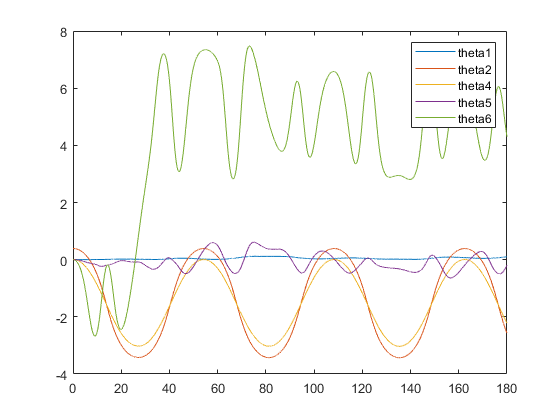

figure();
plot(tt1,Z1(2,:),tt1,Z1(3,:),tt1,Z1(4,:),tt1,Z1(5,:),tt1,Z1(6,:)); 
legend('theta1', 'theta2','theta4','theta5','theta6'); 

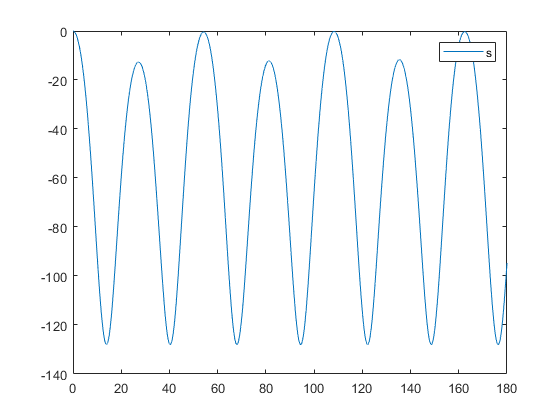

plot(tt1,Z1(1,:)); 
legend('s'); % s in another chart because the scale it's too different

#### Initialize the solver class

solver_P = Heun_P();
solver_P.setODE( ODE );

#### Advance the ODE

DT = 0.1;
T  = 180;

s = 0;
theta1 =0;
theta2 =  0.3912390397;   %theta2 =2.750353614;
theta4 = 0.006780333643;   %theta4 = 3.134812320;
theta5 = 0;
theta6 = 0;
s__dot =0;
theta1__dot = 0;
theta2__dot = 0;
theta4__dot =0;
theta5__dot = 0;
theta6__dot = 0;
Zini = [ s, theta1,theta2,theta4,theta5,theta6 , s__dot, theta1__dot,theta2__dot,theta4__dot,theta5__dot,theta6__dot];

tt0 = 0:DT:T;
tt1 = 0:DT/10:T;
tt2 = 0:DT/100:T;
%Z0 = solver_P.advance( tt0, Zini);
Z1 = solver_P.advance( tt1, Zini);
%Z2 = solver_P.advance( tt2, Zini);

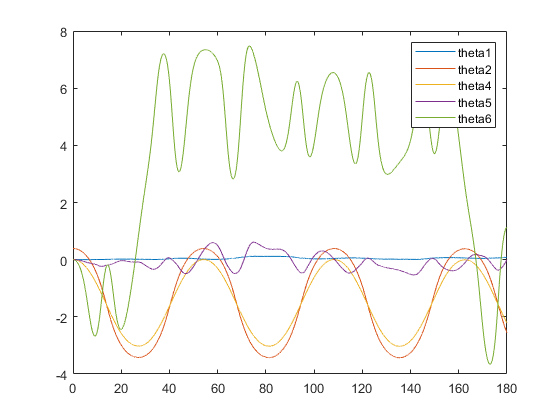

figure();
plot(tt1,Z1(2,:),tt1,Z1(3,:),tt1,Z1(4,:),tt1,Z1(5,:),tt1,Z1(6,:)); 
legend('theta1', 'theta2','theta4','theta5','theta6'); 

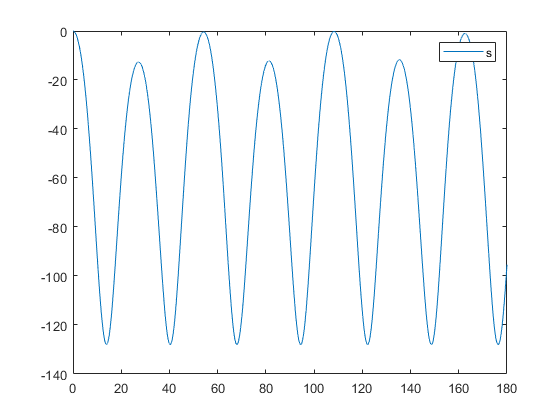

plot(tt1,Z1(1,:)); 
legend('s');